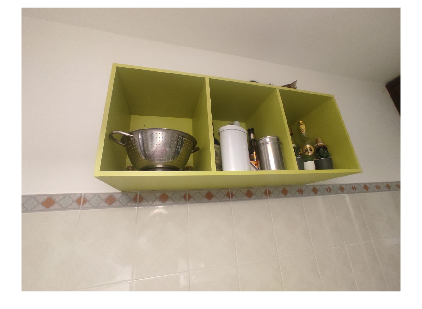

clc; clear all; close all;
%% Manual Feature Extraction (lines)
% Load the image
image = imread('Look-outCat.jpg');
imshow(image);
hold on;


% Number of lines to extract
num_lines = input('Enter the number of lines to extract: ');

% Initialize matrix to store homogeneous line equations
lines_homogeneous = zeros(3, num_lines);

for i = 1:num_lines
    fprintf('Select two points for line %d\n', i);
    
    % Select two points using ginput
    [x, y] = ginput(2);
    plot(x, y, 'r-o', 'LineWidth', 2); % Show selected points on the image
    
    % Homogeneous coordinates of the points
    p1 = [x(1); y(1); 1];
    p2 = [x(2); y(2); 1];
    
    % Compute the line equation (cross product of points)
    line_h = cross(p1, p2);
    
    % Normalize the line equation
    line_h = line_h / (line_h(3));
    
    % Store the line equation
    lines_homogeneous(:, i) = line_h;
    
    fprintf('Line %d equation in homogeneous coordinates: [%f, %f, %f]\n', ...
        i, line_h(1), line_h(2), line_h(3));
end

line_h'*p1
line_h'*p2

% Save the line equations to a .mat file for further use
save('lines_homogeneous.mat', 'lines_homogeneous');
disp('Line equations saved to lines_homogeneous.mat');

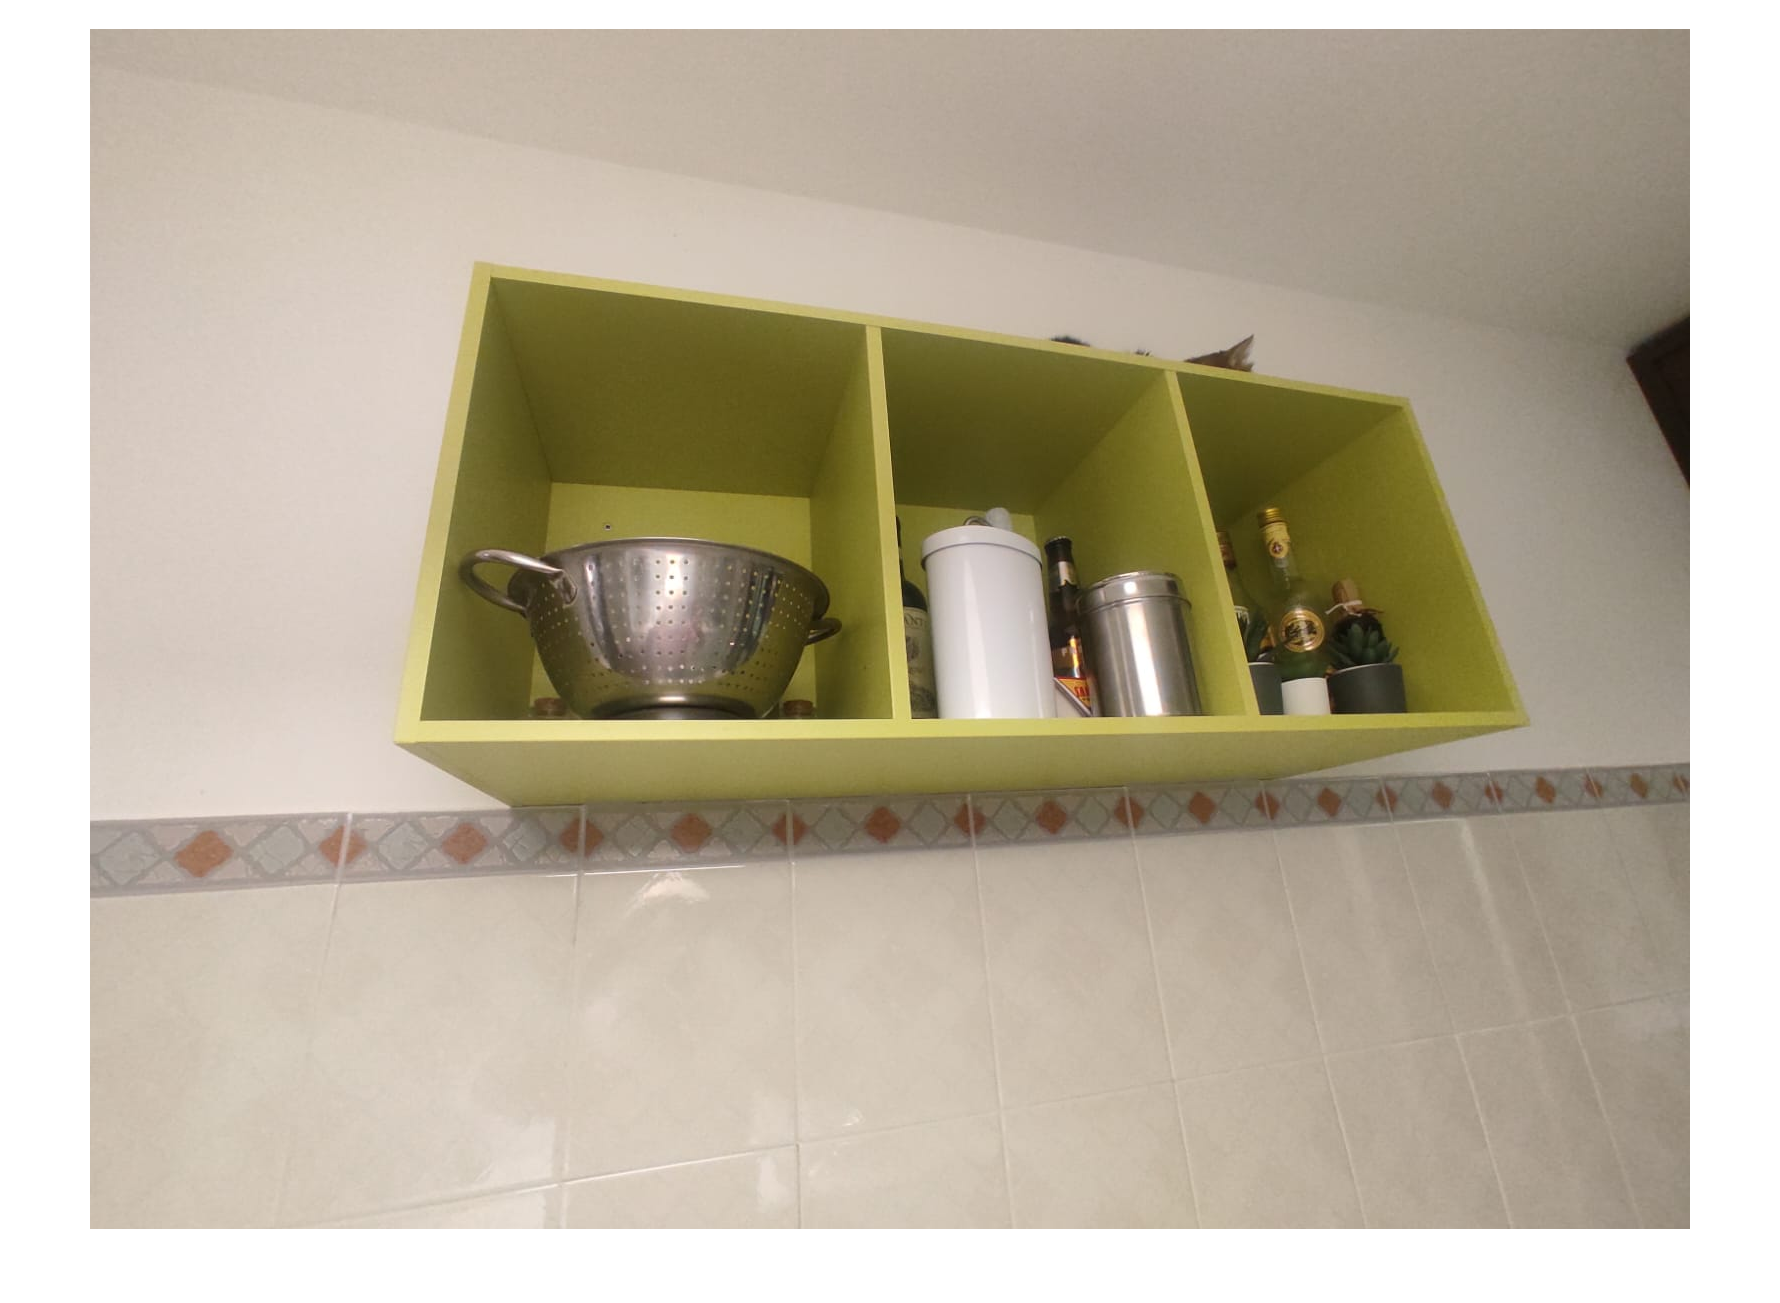

Select two points for line 1


Line 1 equation in homogeneous coordinates: [-0.000023, -0.001390, 1.000000]



%% Manual Feature Extraction (lines+2conics)
clc; clear all; close all;
% Load the image
image = imread('Look-outCat.jpg');


% Number of lines to extract
num_lines = input('Enter the number of lines to extract: ');

% Initialize matrix to store homogeneous line equations
lines_homogeneous = zeros(3, num_lines);

imshow(image);
hold on;

for i = 1:num_lines
    fprintf('Select two points for line %d\n', i);
    
    % Select two points using ginput
    
    [x, y] = ginput(2);
    plot(x, y, 'r-o', 'LineWidth', 2); % Show selected points on the image
    
    % Homogeneous coordinates of the points
    p1 = [x(1); y(1); 1];
    p2 = [x(2); y(2); 1];
    
    % Compute the line equation (cross product of points)
    line_h = cross(p1, p2);
    
    % Normalize the line equation
    line_h = line_h / (line_h(3));

    % Store the line equation
    lines_homogeneous(:, i) = line_h;
    
    fprintf('Line %d equation in homogeneous coordinates: [%f, %f, %f]\n', ...
        i, line_h(1), line_h(2), line_h(3));
end


% Save the line equations to a .mat file for further use
save('lines_homogeneous.mat', 'lines_homogeneous');
disp('Line equations saved to lines_homogeneous.mat');

Line equations saved to lines_homogeneous.mat



line_h'*p1

ans = 3.5562e-17

line_h'*p2

ans = -3.4694e-17

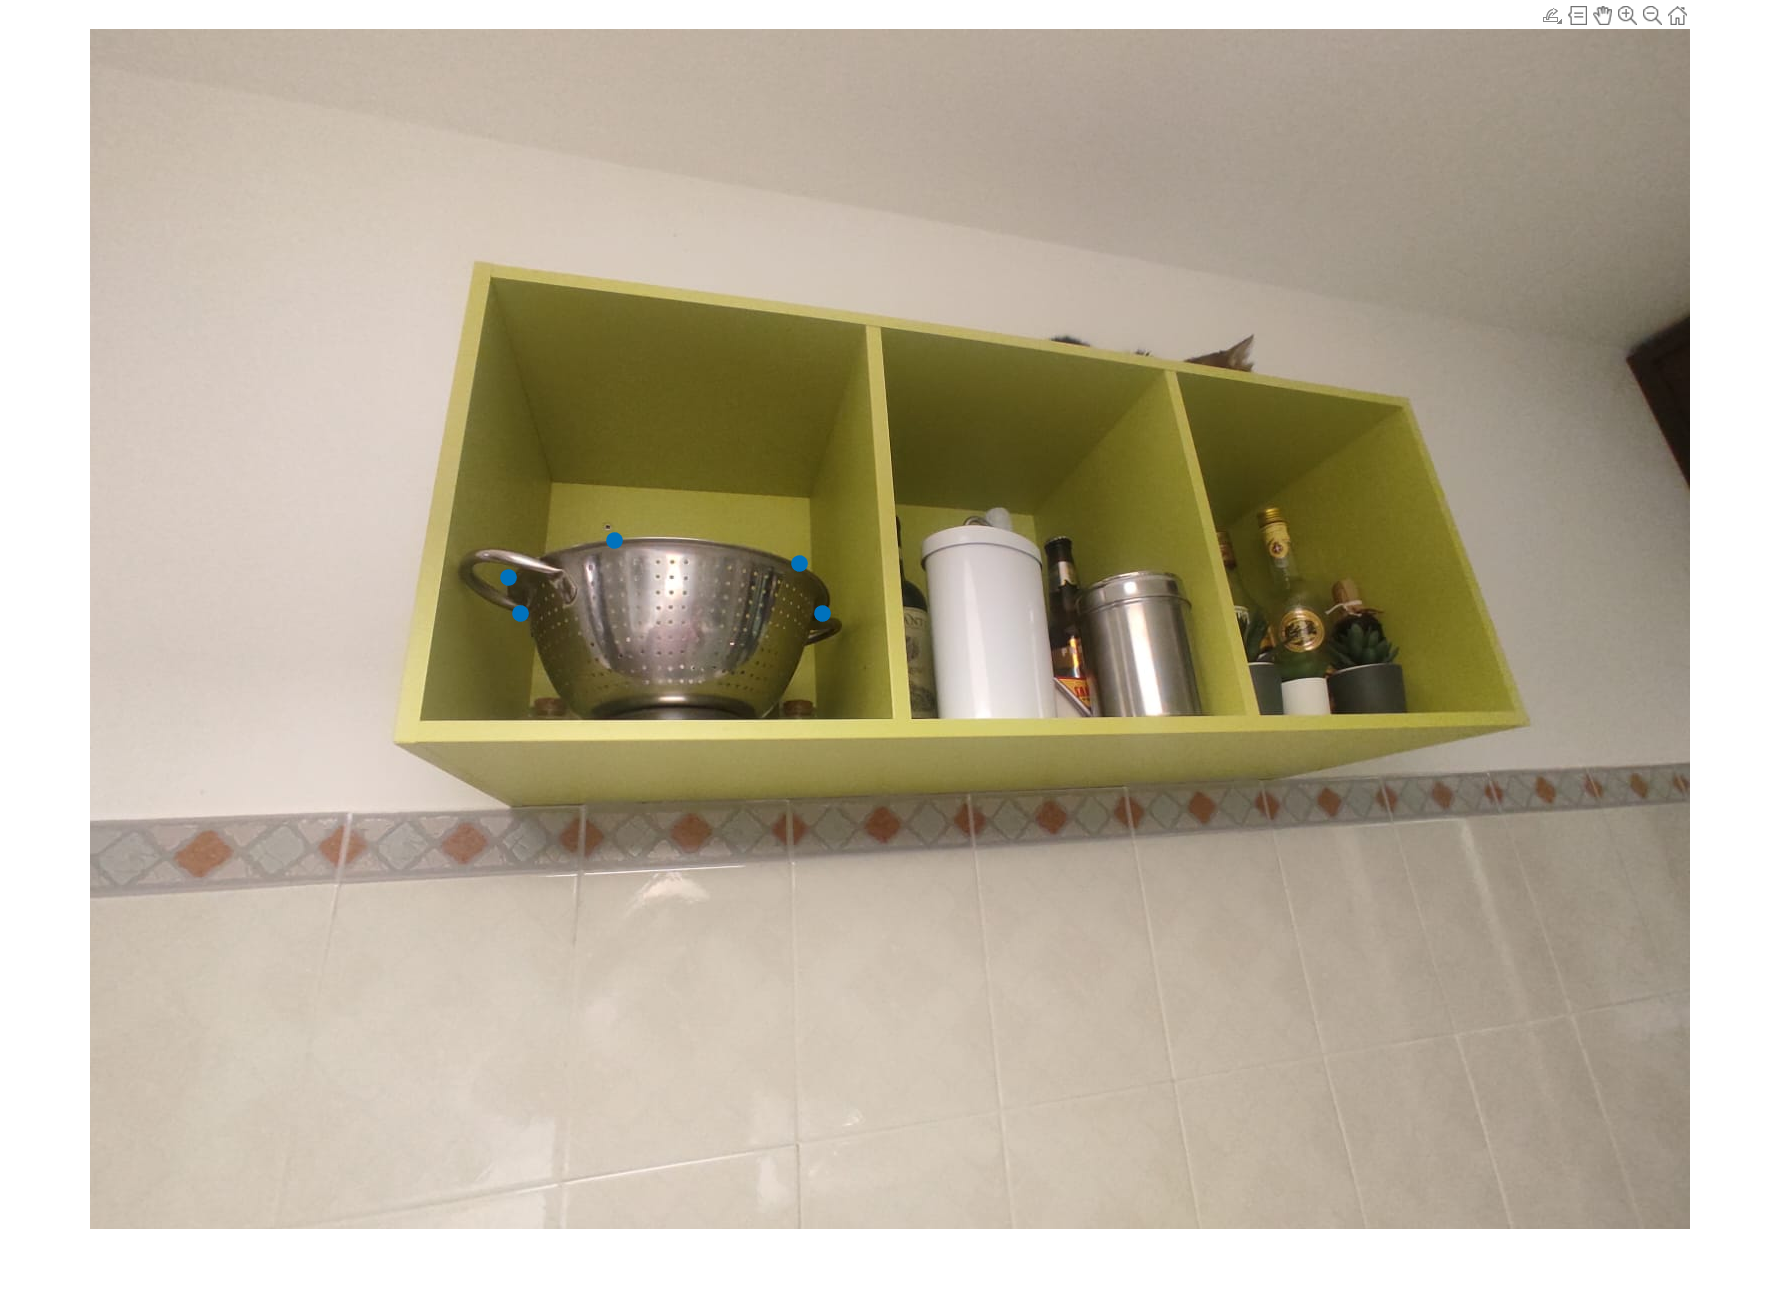

click 5 points, then enter


x =   431.0000
  419.0000
  525.0000
  710.0000
  733.0000


y =    585
   549
   512
   535
   585


A = 1.0e+05 *

    1.8576    2.5213    3.4223    0.0043    0.0059    0.0000
    1.7556    2.3003    3.0140    0.0042    0.0055    0.0000
    2.7562    2.6880    2.6214    0.0052    0.0051    0.0000
    5.0410    3.7985    2.8622    0.0071    0.0053    0.0000
    5.3729    4.2880    3.4223    0.0073    0.0059    0.0000


C =     0.0000   -0.0000   -0.0002
   -0.0000    0.0000   -0.0016
   -0.0002   -0.0016    1.0000



close all;



% Number of conics to extract
num_conics = input('Enter the number of conics to extract: ');

% Initialize a cell array to store conic matrices
conics = cell(1, num_conics);
imshow(image);
hold on;

 for j = 1:num_conics
%     fprintf('Select 6 points to define conic %d\n', j);
% 
%     % Select six points using ginput
% 
%     [x, y] = ginput(6);
%     plot(x, y, 'b-o', 'LineWidth', 2); % Show selected points on the image
% 
%     % Form the design matrix
%     A = [x.^2, x.*y, y.^2, x, y, ones(6, 1)];
% 
%     % Solve for the conic parameters (up to scale)
%     [~, ~, V] = svd(A);
%     conic_params = V(:, end); % Last column of V corresponds to the solution
% 
%     % Reshape the conic parameters into a 3x3 symmetric matrix
%     C = [conic_params(1), conic_params(2)/2, conic_params(4)/2; 
%          conic_params(2)/2, conic_params(3), conic_params(5)/2;
%          conic_params(4)/2, conic_params(5)/2, conic_params(6)];
% 
%     % Store the conic matrix
%     conics{j} = C;
% 
%     fprintf('Conic %d matrix:\n', j);
%     disp(C);
      %%
        % Data input: enter five points (then enter)
        disp('click 5 points, then enter');
        [x, y]=getpts;
        scatter(x,y,100,'filled');
        
        %%
        % x and y are now column vectors.
        x
        y
        
        %% Estimation of conic parameters
        % using the technique shown in "Multiple View Geometry", page 9.
        % this is equivalent to requiring that the conic passes trhough all the six
        % points
        A = [x.^2 x.*y y.^2 x y ones(size(x))]
        
        % A is 5x6: we find the parameter vector (containing [a b c d e f]) as the
        % right null space of A.
        % This returns a vector N such that A*N=0.  Note that this expresses the
        % fact that the conic passes through all the points we inserted.
        N = null(A);
        % alternatively you can use the svd
        [~,~,V] = svd(A); 
        N = V(:,end);
        %%
        % Let's assign the values to variables and build the 3x3 conic matrix
        % (which is symmetrical)
        cc = N(:, 1);
        % change the name of variables
        [a b c d e f] = deal(cc(1),cc(2),cc(3),cc(4),cc(5),cc(6));
        % here is the matrix of the conic: off-diagonal elements must be divided
        % by two
        C=[a b/2 d/2; b/2 c e/2; d/2 e/2 f]
        conics{j} = C;
        % Remark: since the right null space has dimension one,
        % when the points are taken in general position
        % the system admits an infinite number of solutions
        % however, these can be expressed as lambda * n, where n 
        % lambda \in R and n = null(A). 
        % thus, they all corresponds to the same conic.
 end




for i=1:500
    for j=1:500
        im_four1(i,j)=[j i 1]*conics{1}*[j i 1]';
        %im_four2(i,j)=[j i 1]*conics{2}*[j i 1]';
    end
end

Index exceeds the number of array elements. Index must not exceed 1.


figure(2)
subplot(1,2,1)
imshow(im_four1>0);
hold on;
scatter(x(1 : 4), y(1 : 4), 100, 'filled','cyan');
scatter(x(5), y(5), 100, 'filled','red');
title('1st nullspace col ')
subplot(1,2,2)
imshow(im_four2>0);
hold on
scatter(x(1 : 4), y(1 : 4), 100, 'filled','cyan');
scatter(x(5), y(5), 100, 'filled','red');
title('2n nullspace col ')
hold off


% Save the conics to a .mat file for further use
save('conics.mat', 'conics');
disp('Conic matrices saved to conics.mat');
% close all;

im_four=zeros(500,500);
for i=1:500
    for j=1:500
        im_four1(i,j)=[j i 1]*C*[j i 1]';
    end
end

figure(2)
subplot(1,2,1)
imshow(im_four1>0);
hold on;
% scatter(x(1 : 4), y(1 : 4), 100, 'filled','cyan');
% scatter(x(5), y(5), 100, 'filled','red');
% title('1st nullspace col ')
% subplot(1,2,2)
% imshow(im_four2>0);
% hold on
% scatter(x(1 : 4), y(1 : 4), 100, 'filled','cyan');
% scatter(x(5), y(5), 100, 'filled','red');
% title('2n nullspace col ')
hold off

% Load the conics from the .mat file
load('conics.mat', 'conics'); % Ensure the 'conics' variable is available

% Ensure the image is loaded and displayed
figure;
imshow(image);
hold on;

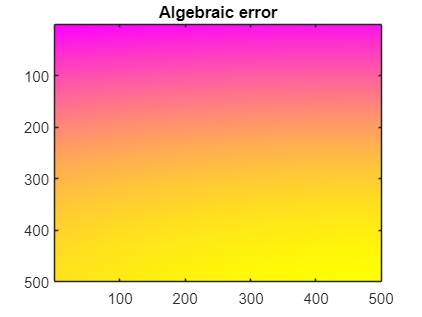


% Define the resolution of the plot
t = linspace(0, 2*pi, 500); % Parameter for the ellipse

% Plot each conic
for i = 1:length(conics)
    C = conics{i}; % Get the conic matrix
    
    % Generate points on the conic
    %[X, Y] = plot_conic(C, t); 
    
    im=zeros(500,500);
    for i=1:500
        for j=1:500
            im(i,j)=[j i 1]*C*[j i 1]'; % this is an algebraic error
        end
    end
    figure; imagesc(im); colormap("spring"); title('Algebraic error');


    % Plot the conic on the image
    %plot(X, Y, 'LineWidth', 2);
    %hold on;
end


title('Detected Conics');
legend('Conic 1', 'Conic 2');

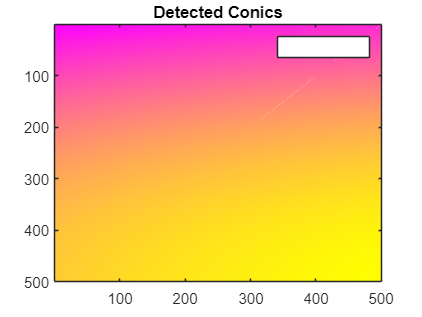

hold off;


% Function to generate (x, y) points for a conic from its matrix